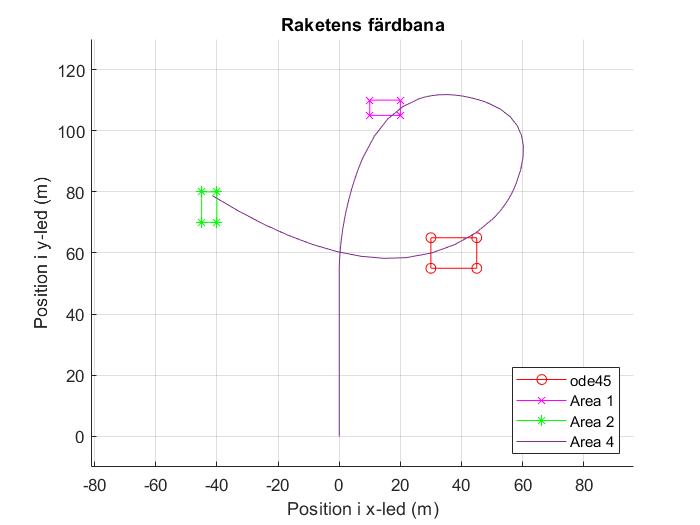

% Projekt 3
% [A,map,transparency] = imread('raket.png');
% imagesc(A)

% raketens startposition är (0,0)
[t,y_ode]=ode45(@ybis,[0 4.9],[0 0 0 0]);
hold on
ylim([-10 130])
xlim([-80 80])



% Målområden
x1 = [30 45 45 30 30];
y1 = [55 55 65 65 55];

x2 = [10 20 20 10 10];
y2 = [105 105 110 110 105];

x4 = [-45 -40 -40 -45 -45];
y4 = [70 70 80 80 70];

% Målområden
plot (x1,y1,'r-o')
plot (x2,y2,'m-x')
plot (x4,y4,'g-*') 

% plotta raketens färdbana
plot(y_ode(:,1),y_ode(:,3)) 
legend('ode45', 'Area 1', 'Area 2', 'Area 4','Location','southeast')

grid on
ylabel('Position i y-led (m)')
xlabel('Position i x-led (m)');

axis equal

%[t,y]=rk2(@ybis,[0 10],[0 0 1 1],20);
title("Raketens färdbana");

hold off

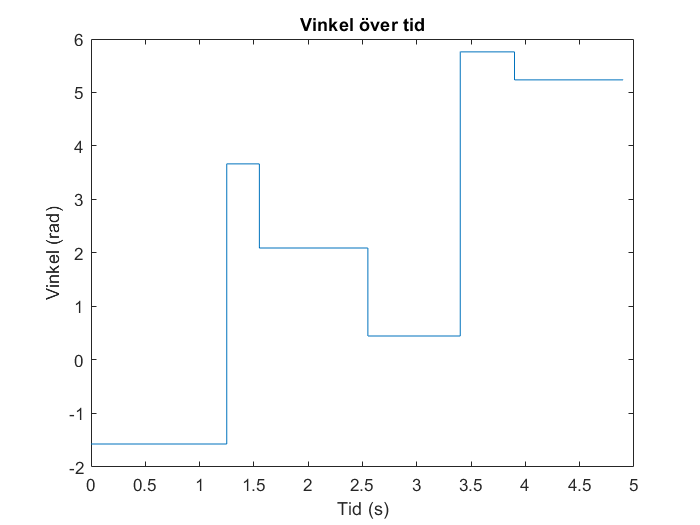

t_v = [0  1.25 1.25 1.55 1.55 2.55 2.55 3.4 3.4 3.9 3.9 4.9];
z_v = [-pi/2 -pi/2 7*pi/6 7*pi/6 2*pi/3 2*pi/3 pi/7 pi/7 11*pi/6 11*pi/6 5*pi/3 5*pi/3];
plot(t_v,z_v)
xlabel('Tid (s)')
ylabel('Vinkel (rad)')
title('Vinkel över tid')

% numerisk lösning
t = linspace(0,10,10000);
%y = (4*sin(3*t))/9-((z(1)*t.^2)/2)-(t/3)+1;
y = cos(t)-(1/2)*sin(t)+(1/2)*sin(3*t);


plot(t,y,'-.') % plotta (z1,z3) = (x,y)


[t_ode,y_ode]=ode45(@ysys,t,[1 1]);
hold on
plot(t_ode,y_ode(:,1),'--') % plotta (z1,z3) = (x,y)

[t_rk2,y_rk2]=rk2(@ysys,[0 10],[1 1],1000);

y =      1     1


plot(t_rk2,y_rk2(:,1),':') % plotta (z1,z3) = (x,y)

[t_rk22,y_rk22]=rk2(@ysys,[0 10],[1 1],100);

y =      1     1


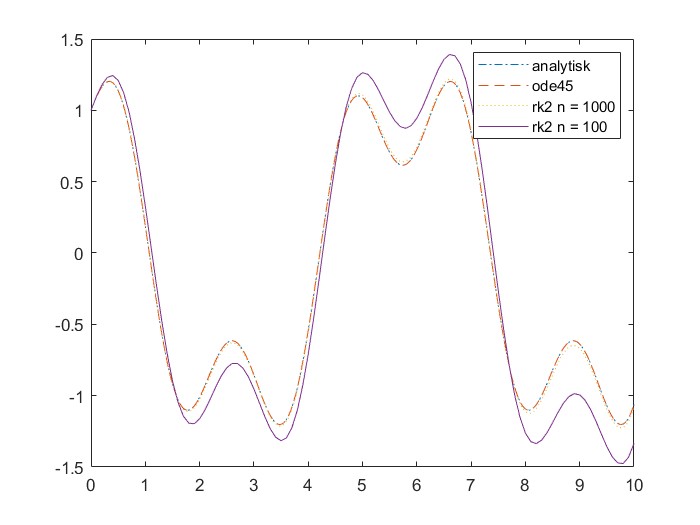

plot(t_rk22,y_rk22(:,1)) % plotta (z1,z3) = (x,y)
legend('analytisk','ode45','rk2 n = 1000', 'rk2 n = 100');
hold off




[t1,y1]  = ode45(@ysys,[0,10],[1 1]);
[t2,y2]  = rk2(@ysys,[0,10],[1 1],1000);

y =      1     1


[t3,y3]  = rk2(@ysys,[0,10],[1 1],100);

y =      1     1



% Berakna analytiskt, fuktionsvarden for motsvarande tidssteg
ye1 = cos(t1)-(1/2)*sin(t1)+(1/2)*sin(3*t1);
ye2 = cos(t2)-(1/2)*sin(t2)+(1/2)*sin(3*t2);
ye3 = cos(t3)-(1/2)*sin(t3)+(1/2)*sin(3*t3);

% Berakna absolutbeloppet av skillnaden 
fel1 = abs(ye1 - y1(:,1));
fel2 = abs(ye2' - y2(:,1));
fel3 = abs(ye3' - y3(:,1));

% Summa
sum1 = sum(fel1);
sum2 = sum(fel2);
sum3 = sum(fel3);

% Medelfel
m1 = sum1/(length(fel1))

m1 = 1.3374e-04

m2 = sum2/(length(fel2))

m2 = 0.0160

m3 = sum3/(length(fel3))

m3 = 0.1732

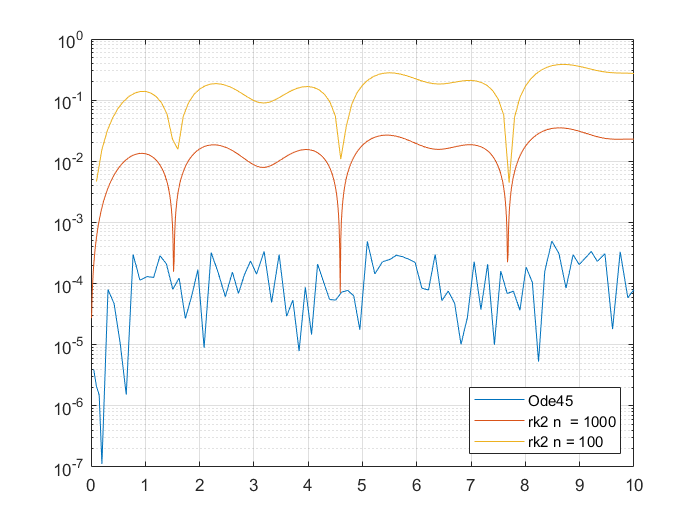



% Plotta 
clf
semilogy(t1,fel1)
hold on
grid on

semilogy(t2,fel2)
semilogy(t3,fel3)
legend('Ode45', 'rk2 n  = 1000', 'rk2 n = 100','Location','southeast');